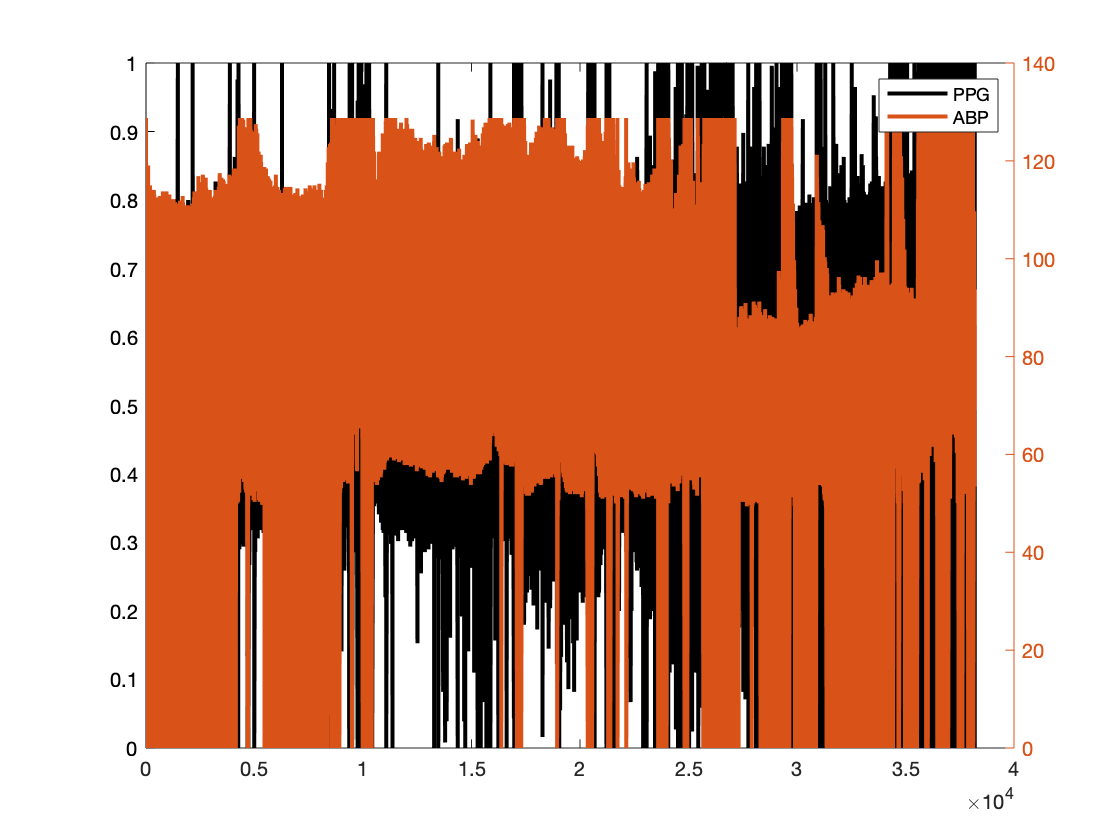

%EXAMPLE IMPORT AND PLOT
record_name = '3000063';
number = '0020';

folder = record_name(1:2);

%data = importdata("../physionet.org/textdata/"+record_name+"_"+number+".txt")

data = cell2mat(textscan( fopen("../physionet.org/textdata/"+record_name+"_"+number+".txt"), ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
Fs=125;
signal = data(:,2:3);
tm = data(:,1);

start_disp = 1;%round(length(tm)/4);
end_disp = length(tm);%%start_disp+3*Fs;
clf
 plot(tm(start_disp:end_disp), signal(start_disp:end_disp,2), 'LineWidth', 2)
hold on
yyaxis right
plot(tm(start_disp:end_disp,1), signal(start_disp:end_disp,1), 'LineWidth',2)
legend("PPG", "ABP")

%FILTERING

%file size thresholding already performed in Python scraper and conversion tool

% Following MIMIC cleaning process in Slapnicar et al. Blood Pressure Estimation from Photoplethysmogram 
%       Using a Spectro-Temporal Deep Neural Network


% Get list of files 
% normalise to zero mean unit variance -> 4th order Butterworth BPF with 0.5 Hz and
% 8Hz cutoffs
orig_file_dir = "../physionet.org/textdata/";
abp_ann_dir = '../physionet.org/abp_ann/';

fileList = dir(orig_file_dir+"*.txt") %only consider all text files

fileList = 192×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


cleaned_file_dir = "../physionet.org/cleaned_data/";
if ~isfolder(cleaned_file_dir)
    mkdir(cleaned_file_dir)
end

regioned_file_dir = "../physionet.org/regioned_data/";
if ~isfolder(regioned_file_dir)
    mkdir(regioned_file_dir)
end


%Filter transfer function
Fs = 125;
% [filt_num, filt_den] = butter(2, 2*pi.*[0.25 20]/(2*pi*Fs),'bandpass')
[filt_num, filt_den] = butter(3, 2*pi.*15/(2*pi*Fs),'low')

filt_num =     0.0048    0.0143    0.0143    0.0048


filt_den =     1.0000   -2.2501    1.7564   -0.4683


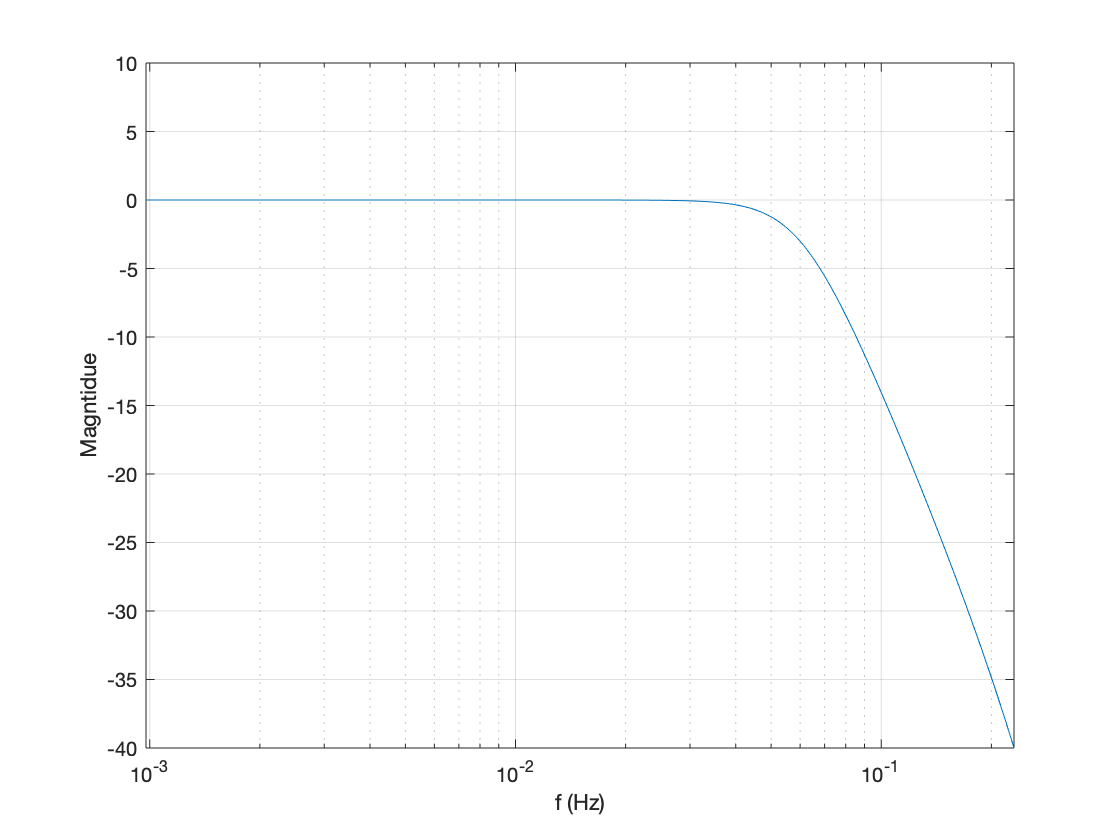

[h,w] =freqz(filt_num, filt_den);
clf
semilogx(w./(2*pi),20.*log10(abs(h)));
ylim([-40,10]);
grid on
xlabel('f (Hz)')
ylabel('Magntidue')

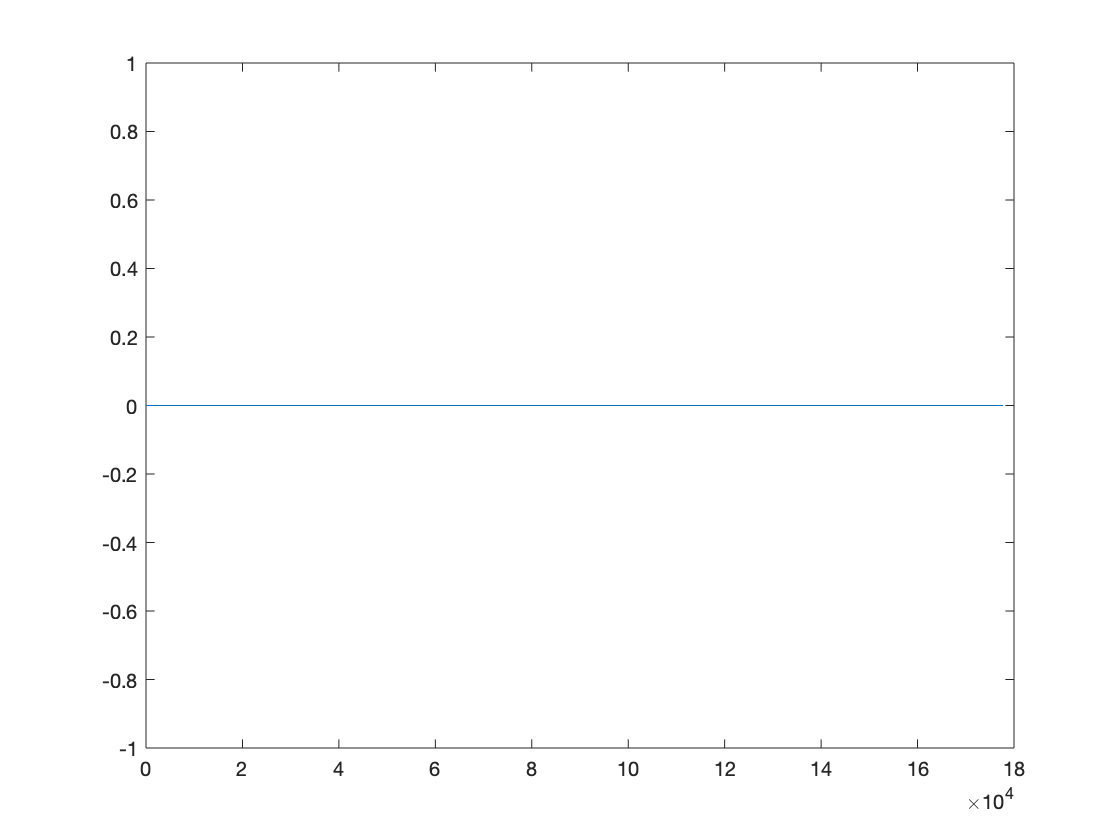




for idx = 1:length(fileList)
    
     dataFile = fopen(orig_file_dir + fileList(idx).name);
     data = cell2mat(textscan( dataFile, ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
     fclose(dataFile);
     
     abpAnnFile = fopen([abp_ann_dir fileList(idx).name(1:end-4) '_abp.txt']);
     locOfAbpBeats = cell2mat(textscan( abpAnnFile, ...
         '%*s %d %*s %*d %*d %*d'));
     fclose(abpAnnFile);
     
%      discard_file = false;
     
     % NB!
     % We need to decide on whether or not to filter ABP data
     % data(:,2) = filter(filt_num, filt_den, data(:,2));
     
     % **** currently not filtering either signal for frequency analysis purposes
%       data(:,3) = filter(filt_num, filt_den, data(:,3));
     
     % Hampel filter to remove outliers
     % data(:,2) = hampel(data(:,2));
     data(:,3) = hampel(data(:,3));
     
     
     invalidABPRegions = findInvalidABPRegions(data(:,2), locOfAbpBeats);
     
     abp_flats = findFlatRegions(data(:,2), 30);
     ppg_flats = findFlatRegions(data(:,3),30);
     all_invalid = abp_flats | ppg_flats | invalidABPRegions;
     
     minSegmentLength = 7500; %corresponds to 1 minute at 125 Hz
     [segmentedSignals, numSegments] = removeInvalidFromSignal(all_invalid, minSegmentLength, data(:,1), data(:,2), data(:,3));
     
     for i=1:numSegments
         out_data = [segmentedSignals{i}{1}{:}, segmentedSignals{i}{2}{:},segmentedSignals{i}{3}{:} ];
         outPath = regioned_file_dir+fileList(idx).name(1:end-4) + "-"+num2str(i)+".txt";
         writematrix(out_data, outPath , 'Delimiter', 'tab');
     end  
end

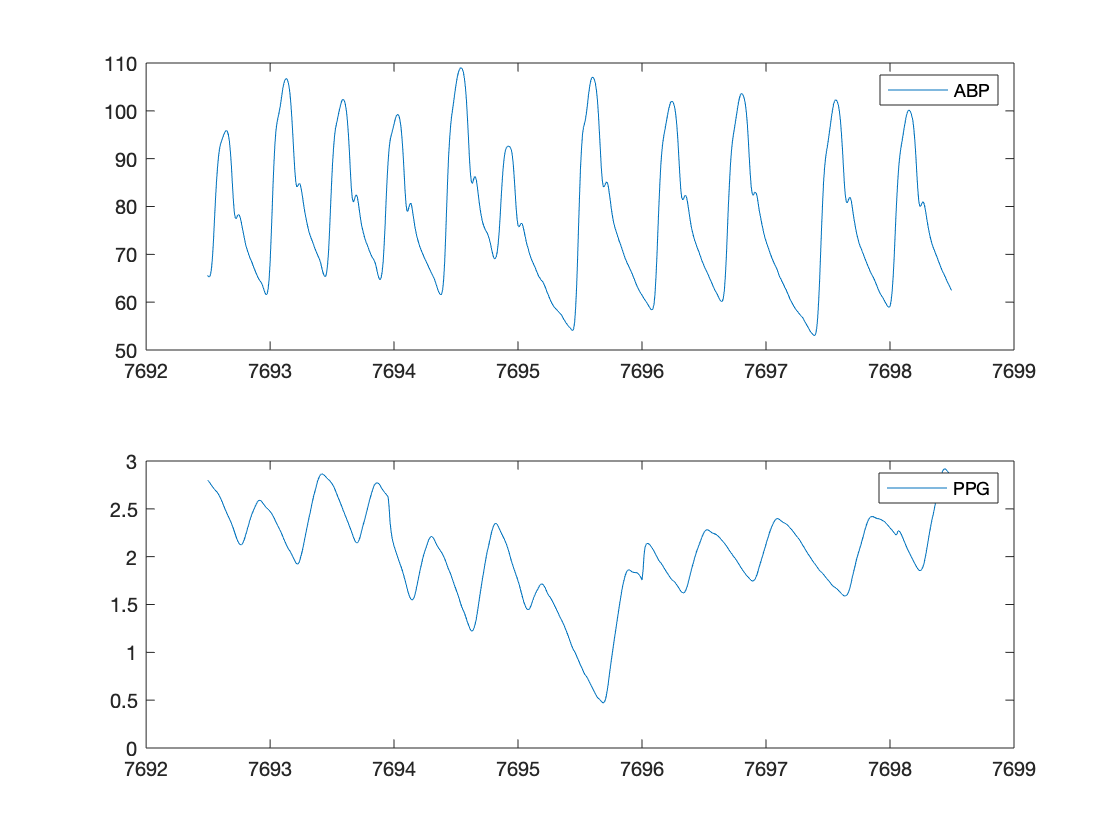

     
%EXAMPLE PLOT

sig = importdata( "../physionet.org/regioned_data/3600271_0023-12.txt");

start_pt = round(length(sig)/4);
end_pt = start_pt + Fs*6;

figure;
subplot(2,1,1)
plot(sig(start_pt:end_pt,1), sig(start_pt:end_pt,2));
legend(["ABP"])

subplot(2,1,2)
plot(sig(start_pt:end_pt,1), sig(start_pt:end_pt,3));
legend(["PPG"])






% *********** ignore ******************
% 
% 
record_name = '3968719';
number = '0014';

folder = record_name(1:2);

data = importdata("../physionet.org/textdata/"+record_name+"_"+number+".txt")

data = 	1.0e+03 *

         0    0.0651    0.0005
    0.0000    0.0675    0.0005
    0.0000    0.0696    0.0005
    0.0000    0.0716    0.0005
    0.0000    0.0731    0.0005
    0.0000    0.0745    0.0005
    0.0000    0.0755    0.0005
    0.0001    0.0763    0.0004
    0.0001    0.0771    0.0004
    0.0001    0.0774    0.0004


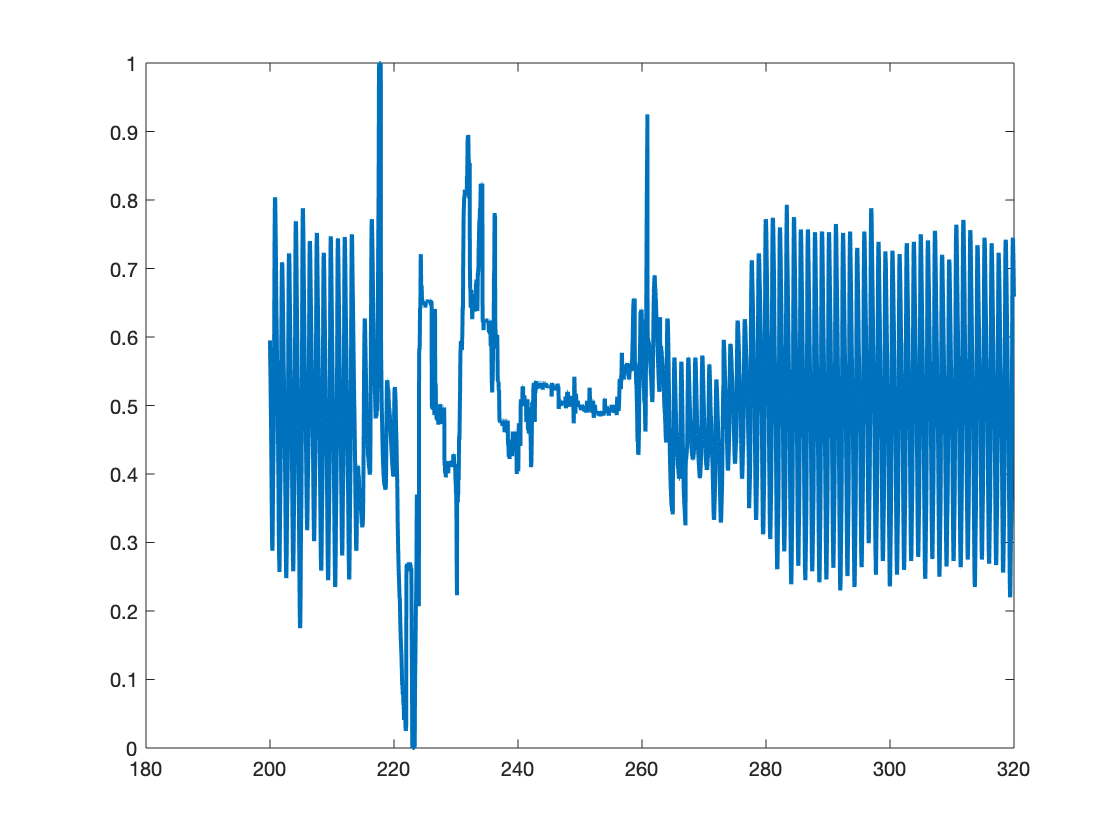


data = cell2mat(textscan( fopen("../physionet.org/textdata/"+record_name+"_"+number+".txt"), ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));

 data = data(25000:40000, :);
Fs=125;
signal = data(:,2:3);
tm = data(:,1);


clf
 plot(tm, signal(:,2), 'LineWidth', 2)

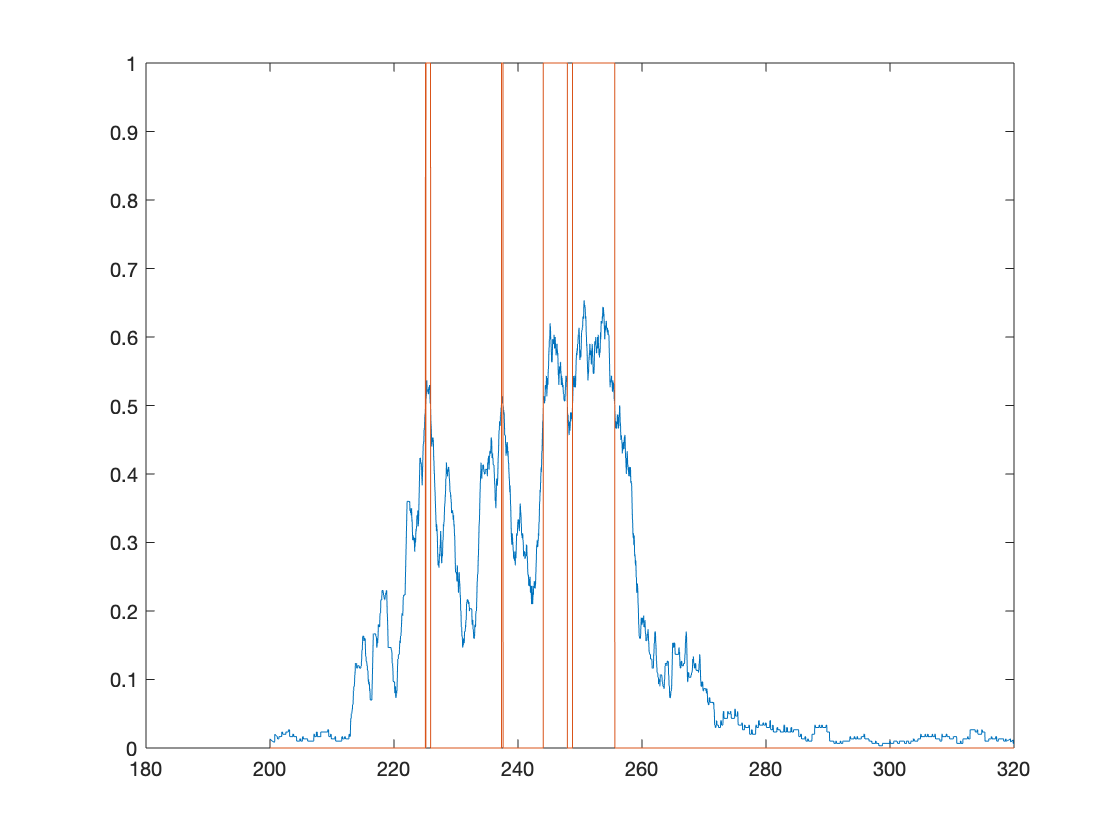

% hold on
% yyaxis right
% plot(tm, signal(:,1), 'LineWidth',2)
% legend("PPG", "ABP")

norm_data = normalize(signal(:,2));


deriv = [0; abs(diff(norm_data))];
tol = 1e-3;
low_grad = deriv < tol;
%then find regions with consecutively low variances
flat_regions = movmean(low_grad, 300);
% diff_check = abs(diff(data))<tol ;
% multiple_pts = 20;
% invalid_portions =  [1; ( movmean(diff_check, multiple_pts-1) < 1)];
% 
clf
plot(tm, flat_regions)
hold on
plot(tm, flat_regions > 0.5)

%  plot(tm, signal(:,2), 'LineWidth', 2)

% 
% 
% [num, den] = butter(4, 2*pi.*3.5/(2*pi*Fs),'high');
% clf
% d = normalize(abs(filter(num, den, data)));
% % plot(tm, d)
% hold on
% plot(tm,movmean(d,30)<-0.9)


% norm_data = normalize(data(:,3));
% clf
% %flat regions will have a variance of approx 0
% moving_variance = movvar(norm_data, 50);
% %then find regions with consecutively low variances
% invalid_regions = movmean(moving_variance <0.01, 200) > 0.4;
% %use |diff| to find changes between okay regions and junk (regions between
% %two spikes are junk)
% segment_indices = [1;find( [0; abs(diff(invalid_regions))] ); length(data)]
% % plot(tm, [0;abs(diff(invalid_regions))] )
% hold on
% plot(tm, data)

f_var = @() findFlatRegions(norm_data, 30, 200);
f_diff = @( ) findFlatRegionsFast(norm_data, 1e-2, 200, 0.4);
timeit(f_var)

ans = 4.6834e-04

timeit(f_diff)

ans = 4.3294e-04